# The MathWorks Power Company

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

You are now an employee of the MathWorks power company, your mission is to design an hydropower plant to provide enough electricity to power all of MathWorks data center in its headquarter in Natick. The project would be to buil an aritificial mountain in the shape of MATLAB's membrane logo with a lake at its center. The lake collects water all year and this water is used to generate

[Cool picture]

## Feasibility study

### Energetic need assesment

u = symunit;
TotalPower = 1425*u.kW

$$TotalPower = 1425\,\mathrm{kW}$$

TotalEnergy = 1425*u.kW*1*u.year

$$TotalEnergy = 1425\,\mathrm{kW}\,{\mathrm{year}}_{\mathrm{Julian}}$$

TotalEnergy = unitConvert(TotalEnergy,u.kW*u.hour)

$$TotalEnergy = 12491550\,h\,\mathrm{kW}$$

### Option 1: Building a dam on the Charles river

CharlesDischarge = 8.6*u.m^3/u.s

$$CharlesDischarge = 8.6000\,\frac{m^{3}}{s}$$

CharlesVolume = CharlesDischarge * 1*unitConvert(u.year,u.s)

$$CharlesVolume = 271395360\,m^{3}$$

deltaPDam = unitConvert(TotalEnergy /CharlesVolume, u.mH2O)

$$deltaPDam = 16.8965\,\mathrm{mH2O}$$

Environmental impact?

### Option 2: Build a large rainwater retention lake

DeltaP = 9.81*1000*10*u.Pa 

$$DeltaP = 98100\,\mathrm{Pa}$$

VolumeWater = TotalEnergy/DeltaP;
VolumeWater = unitConvert(VolumeWater,u.m^3)

$$VolumeWater = 4.5841e+08\,m^{3}$$

AnnualPrecipitation = 1.11*u.m;
SurfaceCaptation = VolumeWater/AnnualPrecipitation

$$SurfaceCaptation = 4.1298e+08\,m^{2}$$

SurfaceCaptation = unitConvert(SurfaceCaptation,u.km^2)

$$SurfaceCaptation = 412.9779\,{\mathrm{km}}^{2}$$

MathWorks is actually going to Solar and Wind instead: [MathWorks Carbon Neutral Innitiative](https://www.mathworks.com/company/aboutus/carbon-neutral.html)

## Modeling power generated from a retention lake

### Introduction

S = 600 * u.km^2

$$S = 600\,{\mathrm{km}}^{2}$$

h = 10 * u.m

$$h = 10\,m$$

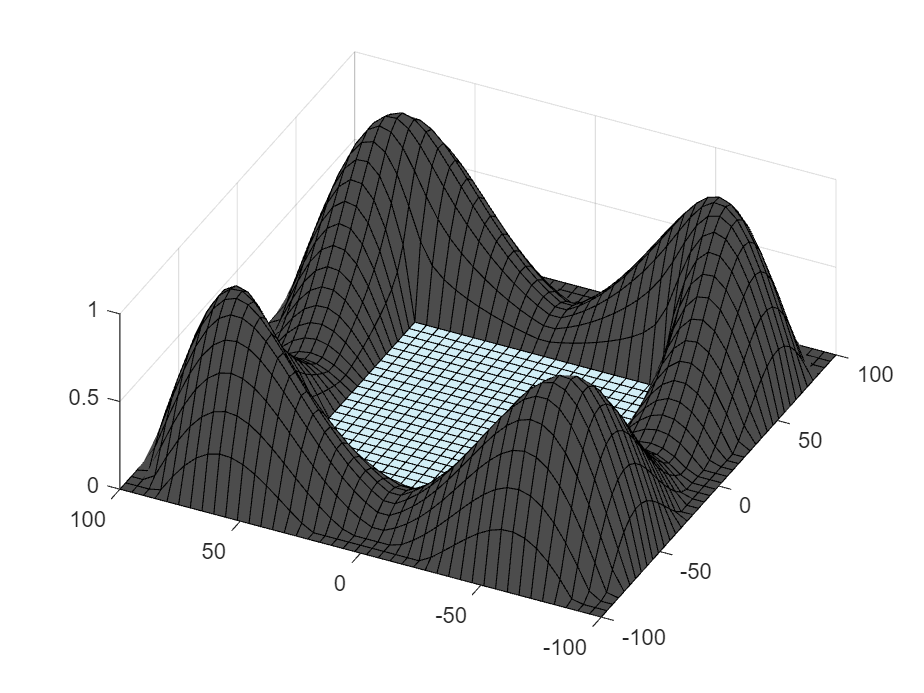

plotRetentionLake()

### Mathematical model


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{res}\frac{dh_\text{res}}{dt} = \dot{m}_\text{rain}-\dot{m}_\text{evap}-\dot{m}_\text{turbine}$$


#### Model the rainfall

load NatickWeather.mat
weather

weather = 515451×5 timetable
            time             Temp      Wind      RH    Rainfall    DewPoint
    ____________________    ______    _______    __    ________    ________
    01-Jan-2022 00:00:10    6.5556          0    91       0         4.7556 
    01-Jan-2022 00:01:10    6.5556          0    91       0         4.7556 
    01-Jan-2022 00:02:10    6.5556          0    91       0         4.7556 
    01-Jan-2022 00:03:10    6.5556          0    91       0         4.7556 
    01-Jan-2022 00:04:10    6.5556          0    91       0         4.7556 
    01-Jan-2022 00:05:10    6.5556    0.22352    91       0         4.7556 
    01-Jan-2022 00:06:10    6.5556      

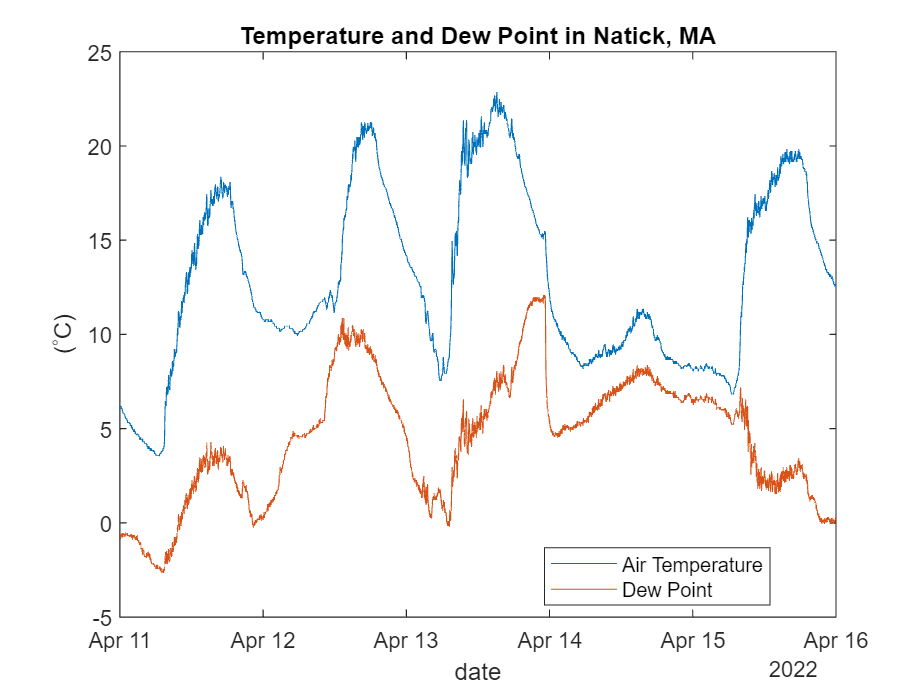

figure
plot(weather,"time","Temp")
hold on
plot(weather,"time","DewPoint")
hold off
title("Temperature and Dew Point in Natick, MA")
ylabel("(^\circ{C})")
xlabel("date")
legend("Air Temperature", "Dew Point","Location","best")
firstDate = datetime(2022,4,11);
Duration = 5;
xlim([firstDate,firstDate+Duration*days]);

% Retime timetable
dailyWeather = retime(weather(:,[1 2 3 5]),"regular","mean",...
    "TimeStep",caldays(1));

% Retime each override variable to same time vector
TT = retime(weather(:,"Rainfall"),dailyWeather.Properties.RowTimes,"sum");
dailyWeather = addvars(dailyWeather,TT.(1),'Before',4,...
    'NewVariableNames',"Rainfall");
clear TT

% Display results
dailyWeather

dailyWeather = 365×5 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint
    ___________    ________    _______    ______    ________    ________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381 
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752 
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912 
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403 
    05-Jan-2022      3.0132     1.8485    89.962     6.4262      1.0056 
    06-Jan-2022      1.9187     1.4706    73.631          0     -3.3551 
    07-Jan-2022     -2.2704      1.632    85.014          0   

dailyWeather.E0 = (700*dailyWeather.Temp/(100-42.3)+15*(dailyWeather.Temp-dailyWeather.DewPoint))./(80-dailyWeather.Temp)

dailyWeather = 365×6 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint      E0   
    ___________    ________    _______    ______    ________    ________    _______
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381      1.6737
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752      1.2542
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912     0.81681
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403       1.204
    05-Jan-2022      3.0132     1.8485    89.962     6.4262      1.0056     0.86597
    06-Jan-2022      1.9187     1.4706   

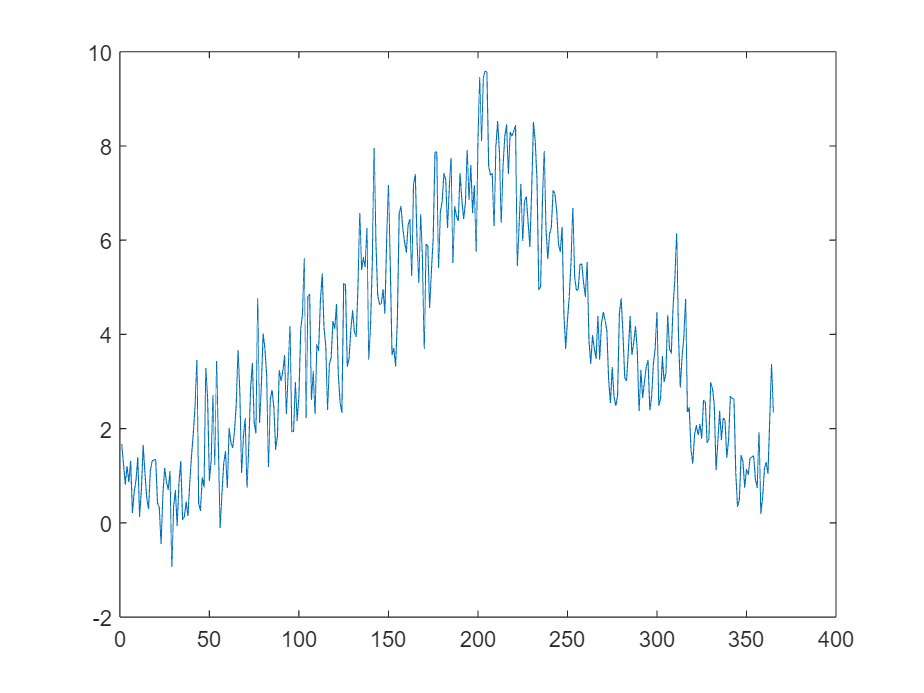

plot(dailyWeather.E0)

#### Model the evaporation

#### Model the flow through the turbine

## Helper Functions

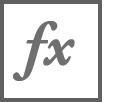`plotRetentionLake()`

function plotRetentionLake()
    Z = membrane(1,10);
    Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
    n = size(Z,1);
    [X,Y] = meshgrid(0:n-1,0:n-1);
    X = 2*X/(n-1) - 1;
    Y = 2*Y/(n-1) - 1;
    C = zeros(size(Z));
    C(11:31,11:31) = 1.0;
    Z(1,:) = 0.0;
    Z(end,:) = 0.0;
    Z(:,1) = 0.0;
    Z(1,end) = 0.0;
    Z( Z < 0 ) = 0.0;
    X = X * 100;
    Y = Y * 100;
    s = surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
    view([-64 59])
    mapFace = [0.3 0.3 0.3
               0.83 0.94 0.97];
    colormap(mapFace)
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc